# Inlet design 

¿Se satisfacen condiciones de recuperación? ✅
η_r: 0.5432
η_min: 0.5126
δ_total: 56.7383º
Ondas de choque: Oblicuas: 4
                 Normales: 1


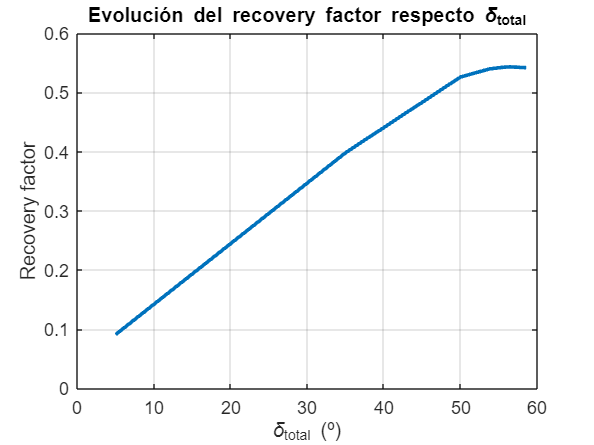

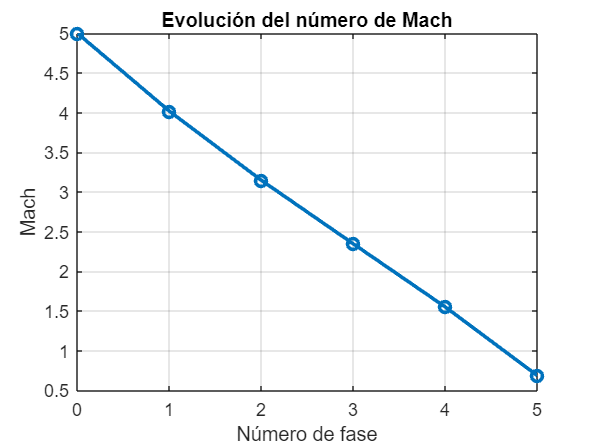

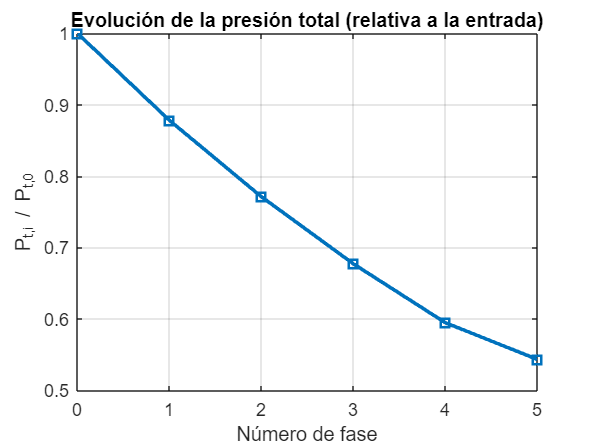

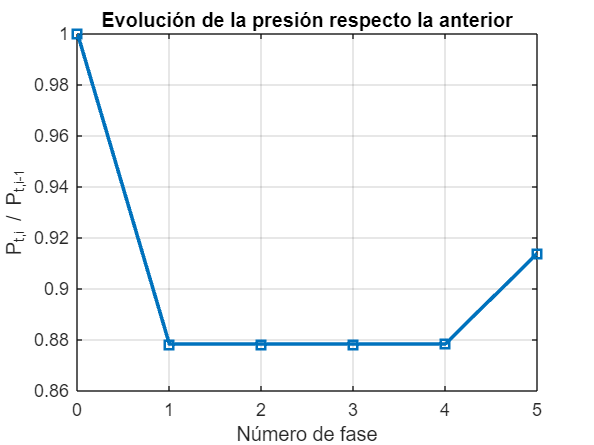

clear;

% DATOS FÍSICOS

M0 = 5;                    % Mach incial
gama = 1.4;                % Relación de calores específicos

% DATOS NUMÉRICOS PREVIOS

N = 4;                     % Número de ondas de choque oblicuas
suma = deg2rad(0.1);       % Variaciones de delta mínima a cumplir (rad)
delta_inicial = deg2rad(5);    % Delta inicial (rad)

% RESULTADOS PARA N ONDAS OBLICUAS

data = optim_calc(M0,gama,N,delta_inicial,suma);

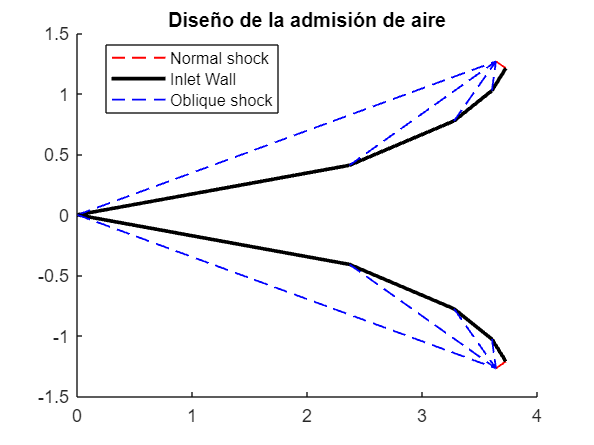



x_shocks_intersection = 3.640160697914008; % Valor para posterior graficado del turboreactor 

inlet_design(N,data.delta_i,data.theta_i,x_shocks_intersection)

% N = num oblique shocks
% x_shocks_intersection = distancia x a la que las ondas de choque
% interseccionan (sirve para ajustar el tamaño del inlet) 


% COMPARACION PARA CUANDO delta_i NO SE OPTIMIZA Y SE UTILIZA delta_i =
% delta_total/N

% comparacion_Nshocks(M0,gama,N,suma,data)

% ONDA OBLICUA + NORMAL

% oblique_normal_shocks(M0,gama)


% RELACION DE ESTANCAMIENTO

st1 = stagnation(data.M1,gama);
st0 = stagnation(M0,gama);

presiones = data.eta_r_max * st0.Pt_P / st1.Pt_P;



## Funciones

### Caso de onda oblicua + normal

function  oblique_normal_shocks(M0,gama)


% Convertir delta objetivo a radianes
delta_target_deg = 22;
delta_target_rad = deg2rad(delta_target_deg);

% --- Inicio de la sección para calcular propiedades sobre un rango de theta ---
% Este barrido se usa principalmente para generar los gráficos.

% Rango de ángulos de onda theta (en grados) desde el ángulo de Mach hasta 90
thetad = linspace(asind(1/M0), 90, 180); % Usamos más puntos para gráficos más suaves
theta_rad = deg2rad(thetad);       % Convertir a radianes para cálculos

% Inicializar arrays para almacenar los resultados del barrido
delta_rad = zeros(1, length(theta_rad));
M1 = zeros(1, length(theta_rad));
Pt15_Pt0 = zeros(1, length(theta_rad)); % P_t1 / P_t0
M15 = zeros(1, length(theta_rad));
Pt1_Pt15 = zeros(1, length(theta_rad)); % P_t15 / P_t1

% Bucle para calcular las propiedades para cada ángulo theta en el barrido
for i = 1:length(theta_rad)
    ob1 = oblique_SW(M0, gama, theta_rad(i));
    delta_rad(i) = ob1.delta;
    M1(i) = ob1.M2;
    Pt15_Pt0(i) = ob1.pt2_pt1; % P_t1 / P_t0

    relT_ob = ob1.relacion_T2_T1;
    relP_ob = ob1.relacion_p2_p1;

    if M1(i) > 1
        nor15 = normal_SW(M1(i), gama);
        M15(i) = nor15.M2;
        Pt1_Pt15(i) = nor15.pt2_pt1; % P_t15 / P_t1
        relT(i) = relT_ob * nor15.relacion_T2_T1;
        relP(i) = relP_ob * nor15.relacion_P2_P1;
    else
        M15(i) = M1(i);
        Pt1_Pt15(i) = 1; % P_t15 / P_t1 = 1 if no normal shock
        relT(i) = relT_ob;
        relP(i) = relP_ob;
    end
end

% Convertir delta del barrido a grados para graficar
deltad = rad2deg(delta_rad);

% Calcular la relación de presión total global P_t15/P_t0
eta_r = Pt15_Pt0 .* Pt1_Pt15;

R = 287;                           % J/kg·K (Constante de gases, asumiendo aire)
% La entropía generada a través de un proceso adiabático con cambio en Pt es: s_gen = -R * ln(Pt_despues / Pt_antes)
sgen_sweep = R*gama/(gama-1)*log(relT) -R * log(relP); % J/kg·K


% Encontrar el delta máximo del barrido (útil para gráficos y validación)
[delta_max_deg, idx_max_delta] = max(deltad);


% --- Figura 1: Subplots vs theta (Layout 2x2) ---
figure; 

% Subplot 1: delta vs theta
subplot(2,2,1);
plot(thetad, deltad, 'b', 'LineWidth', 1.5);
grid on;
xlabel('\theta (º)');
ylabel('\delta (º)');
title('a) \delta vs \theta');
xlim([min(thetad) max(thetad)]);
ylim([min(deltad)-1 max(deltad)+1]);

% Subplot 2: Números de Mach vs theta
subplot(2,2,2);
plot(thetad, M1, 'r', thetad, M15, 'g', 'LineWidth', 1.5);
grid on;
xlabel('\theta (º)');
ylabel('Número de Mach');
legend('M_{15}','M_{1}', 'Location','best');
title('b) Número de Mach vs \theta');
xlim([min(thetad) max(thetad)]);
ylim([min([M1 M15])-0.2 max([M1 M15])+0.2]);

% Subplot 3: Relaciones de presiones totales vs theta
subplot(2,2,3);
plot(thetad, Pt15_Pt0, 'm', thetad, Pt1_Pt15, 'c', 'LineWidth', 1.5);
grid on;
xlabel('\theta (º)');
ylabel('Relación de presiones totales');
legend('P_{t15}/P_{t0}','P_{t1}/P_{t15}', 'Location','best');
title('c) Relaciones de presiones totales vs \theta');
xlim([min(thetad) max(thetad)]);
ylim([min([Pt15_Pt0 Pt1_Pt15])-0.05 max([Pt15_Pt0 Pt1_Pt15])+0.05]);

% Subplot 4: Eficiencia de recuperación vs theta
subplot(2,2,4);
plot(thetad, eta_r, 'k', 'LineWidth', 1.5);
grid on;
xlabel('\theta (º)');
ylabel('\eta_r');
title('d) Recovery factor vs \theta');
xlim([min(thetad) max(thetad)]);
ylim([min(eta_r)-0.05 max(eta_r)+0.05]);


% --- Figura 2: Subplots vs delta hasta delta_max (Layout 2x2) ---
figure; 

% Subplot 1: theta vs delta
subplot(2,2,1);
% Solo graficamos hasta el punto de delta maximo
plot(deltad(1:idx_max_delta), thetad(1:idx_max_delta), 'b', 'LineWidth', 1.5);
grid on;
ylabel('\theta (º)'); % Eje Y es theta
xlabel('\delta (º)'); % Eje X es delta
title('a) \theta vs \delta');
xlim([min(deltad(1:idx_max_delta)) max(deltad(1:idx_max_delta))]);
ylim([min(thetad(1:idx_max_delta))-1 max(thetad(1:idx_max_delta))+1]);

% Subplot 2: Mach numbers vs delta
subplot(2,2,2);
plot(deltad(1:idx_max_delta), M1(1:idx_max_delta), 'r', deltad(1:idx_max_delta), M15(1:idx_max_delta), 'g', 'LineWidth', 1.5);
grid on;
xlabel('\delta (º)');
ylabel('Número de Mach');
legend('M_{15}','M_{1}', 'Location','best');
title('b) Número de Mach vs \delta');
xlim([min(deltad(1:idx_max_delta)) max(deltad(1:idx_max_delta))]);
ylim([min([M1(1:idx_max_delta) M15(1:idx_max_delta)])-0.2 max([M1(1:idx_max_delta) M15(1:idx_max_delta)])+0.2]);

% Subplot 3: Relaciones de presiones totales vs delta
subplot(2,2,3);
plot(deltad(1:idx_max_delta), Pt15_Pt0(1:idx_max_delta), 'm', deltad(1:idx_max_delta), Pt1_Pt15(1:idx_max_delta), 'c', 'LineWidth', 1.5);
grid on;
xlabel('\delta (º)');
ylabel('Relación de presiones totales');
legend('P_{t15}/P_{t0}','P_{t1}/P_{t15}', 'Location','best');
title('c) Relaciones de presiones totales vs \delta');
xlim([min(deltad(1:idx_max_delta)) max(deltad(1:idx_max_delta))]);
ylim([min([Pt15_Pt0(1:idx_max_delta) Pt1_Pt15(1:idx_max_delta)])-0.05 max([Pt15_Pt0(1:idx_max_delta) Pt1_Pt15(1:idx_max_delta)])+0.05]);

% Subplot 4: Eficiencia de recuperación vs delta
subplot(2,2,4);
plot(deltad(1:idx_max_delta), eta_r(1:idx_max_delta), 'k', 'LineWidth', 1.5);
grid on;
xlabel('\delta (º)');
ylabel('\eta_r');
title('d) Recovery factor vs \delta');
xlim([min(deltad(1:idx_max_delta)) max(deltad(1:idx_max_delta))]);
ylim([min(eta_r(1:idx_max_delta))-0.05 max(eta_r(1:idx_max_delta))+0.05]);


% --- Figura 3: Gráfico  para Entropía Generada (sgen) vs theta ---
figure; 
plot(thetad, sgen_sweep, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('\theta (º)');
ylabel('s_{gen} (J/kg·K)');
title('Entropía generada vs \theta'); 
xlim([min(thetad) max(thetad)]);
ylim([min(sgen_sweep)-5 max(sgen_sweep)+5]); 
hold on; 


% --- Inicio de la sección para encontrar theta y sgen para un delta_target_deg dado ---


% Verificar si el delta objetivo es alcanzable (es decir, menor o igual al delta_max)
% delta_max_deg ya se calculó anteriormente
if delta_target_deg > delta_max_deg
    fprintf('Advertencia: El delta objetivo (%.2f°) es mayor que el delta máximo alcanzable (%.2f°) para M0=%.2f.\n', delta_target_deg, delta_max_deg, M0);
    fprintf('No existen soluciones de theta para este delta objetivo.\n');
    theta_solutions_deg = [];
    sgen_solutions = [];
else
   
    delta_target_rad = deg2rad(delta_target_deg);

    f_theta_find_root = @(theta_rad) atan( (2.*cot(theta_rad) .* (M0.^2 .* sin(theta_rad).^2 - 1)) ./ ...
                                          (M0.^2 .* (gama + cos(2.*theta_rad)) + 2) ) - delta_target_rad;

    theta_min_possible_rad = asin(1/M0);
    theta_search_range_rad = linspace(theta_min_possible_rad + 1e-6, pi/2 - 1e-6, 2000); % Barrido fino

    % Evaluar la función en el rango de búsqueda
    f_vals_search = arrayfun(f_theta_find_root, theta_search_range_rad);

    % Encontrar los índices donde hay un cambio de signo (cruces por cero)
    sign_changes_idx_search = find(diff(sign(f_vals_search)));

    theta_solutions_rad = []; % Array para almacenar las soluciones de theta encontradas (en radianes)

    if isempty(sign_changes_idx_search)
         fprintf('Advertencia: No se encontraron intervalos con cambio de signo para delta = %.2f° y M = %.2f dentro del rango de búsqueda.\n', delta_target_deg, M0);
         fprintf('Puede que el delta dado no tenga solución en el rango 0 < theta < 90 para este Mach.\n');
    else
        % Iterar a través de los cambios de signo para encontrar las raíces con fzero
        for k = 1:length(sign_changes_idx_search)
            interval_low_rad = theta_search_range_rad(sign_changes_idx_search(k));
            interval_high_rad = theta_search_range_rad(sign_changes_idx_search(k)+1);

            try
                % Encontrar la raíz (la solución de theta en radianes) dentro del intervalo
                root_rad = fzero(f_theta_find_root, [interval_low_rad, interval_high_rad]);

                if isreal(root_rad)
                     if isempty(theta_solutions_rad) || min(abs(theta_solutions_rad - root_rad)) > 1e-5 % Tolerancia para considerar raíces únicas
                         theta_solutions_rad = [theta_solutions_rad, root_rad];
                     end
                end

            catch
                fprintf('Advertencia: Error en fzero al buscar raíz en el intervalo [%.4f, %.4f] rad.\n', interval_low_rad, interval_high_rad);
            end
        end
    end

    % Ordenar las soluciones de theta encontradas y convertirlas a grados
    theta_solutions_rad = sort(theta_solutions_rad);
    theta_solutions_deg = rad2deg(theta_solutions_rad);

    % --- Calcular propiedades (incluyendo sgen) para las soluciones de theta encontradas ---
    sgen_solutions = zeros(1, length(theta_solutions_rad));

    if ~isempty(theta_solutions_rad)
        fprintf('\nResultados para delta_target = %.2f°:\n', delta_target_deg);
        for j = 1:length(theta_solutions_rad)
            current_theta_rad = theta_solutions_rad(j);

            % Recalcular Pt15/Pt0 para este angulo theta solución preciso
            ob1_sol = oblique_SW(M0, gama, current_theta_rad);
            M1_sol = ob1_sol.M2;
            Pt1_Pt0_sol = ob1_sol.pt2_pt1; % P_t1 / P_t0

            if M1_sol > 1
                nor15_sol = normal_SW(M1_sol, gama);
                M15_sol = nor15_sol.M2; % Guardar M15 si se necesita
                Pt15_Pt1_sol = nor15_sol.pt2_pt1; % P_t15 / P_t1
                Pt15_Pt0_sol_total = Pt1_Pt0_sol * Pt15_Pt1_sol; % P_t15 / P_t0
            else
                % Si M1 <= 1, no hay onda normal subsiguiente
                 M15_sol = M1_sol; % M15 = M1
                Pt15_Pt0_sol_total = Pt1_Pt0_sol; % P_t15/P_t0 = P_t1/P_t0
            end

            % Calcular sgen para esta solución usando la relación de presión total
            sgen_solutions(j) = -R * log(Pt15_Pt0_sol_total); % J/kg·K

            fprintf('  Solución %d:\n', j);
            fprintf('    θ = %.4f°\n', theta_solutions_deg(j));
            fprintf('    Entropía generada (sgen) = %.4f J/kg·K\n', sgen_solutions(j));
        end
    else
        fprintf('No se encontraron soluciones de theta para delta = %.2f° dentro del rango de búsqueda.\n', delta_target_deg);
    end
end

% --- Marcar los puntos encontrados en el GRÁFICO SEPARADO de sgen vs theta ---
% La Figura 3 (el gráfico de sgen) ya está activa y en 'hold on'.

if ~isempty(theta_solutions_deg)
    plot(theta_solutions_deg, sgen_solutions, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
    for j = 1:length(theta_solutions_deg)
         vertical_align = 'bottom';
         horizontal_align = 'left';
         if length(theta_solutions_deg) > 1
             if j == 1 && theta_solutions_deg(2) > theta_solutions_deg(1)
             elseif j == 2 && theta_solutions_deg(2) > theta_solutions_deg(1)
                  horizontal_align = 'right'; 
             end
         end

   %      text(theta_solutions_deg(j), sgen_solutions(j), sprintf(' %.2fº', theta_solutions_deg(j)), ...
   %          'VerticalAlignment', vertical_align, 'HorizontalAlignment', horizontal_align, 'Color', 'red');
    end
end
hold off; 

end


### Caso de N ondas oblicuas

function data = N_oblique_shocks(M0,gama,N,delta_inicial,suma)

eta_r_min = 1 - 0.075 * (M0 - 1)^1.35;
recovery_menor = true; i = 1; 

delta_tot = delta_inicial;

while recovery_menor == true

[d_opt, eta_r(i)] = optimize_delta(M0, gama, N, delta_tot(i));

if i == 1 
    d_opt_max = d_opt;
else 
    if eta_r(i) > eta_r(i-1)
        d_opt_max = d_opt;
    else
        recovery_menor = false;
        break
    end
end

delta_tot(i+1) = delta_tot(i) + suma;
i = i + 1;
end

data.delta_i = d_opt_max;
% data.theta_i = find_theta(M1,gama,sum(d_opt_max));
data.eta_r_max = max(eta_r);


end

### Optimizar tiempo de cálculo

function data = optim_calc(M0,gama,N,delta_inicial,suma)

eta_r_min = 1 - 0.075 * (M0 - 1)^1.35;

suma_i = deg2rad(15);
error_peque = false;
i = 1;

delta_tot = delta_inicial;

while error_peque == false
    data = N_oblique_shocks(M0,gama,N,delta_tot(i),suma_i);
    [~,eta_r(i)] = optimize_delta(M0, gama, N, delta_tot(i));

    if suma_i <= suma
        error_peque = true;
    else
        delta_tot(i+1) = sum(data.delta_i) - suma_i;
        suma_i = suma_i/2;
        i = i + 1;
    end
end

delta_tot(end+1) = delta_tot(end)+deg2rad(2);
[~,eta_r(end+1)] = optimize_delta(M0, gama, N,delta_tot(end));

% Obtener los valores de Mach, Pt y theta para cada fase:

for i = 1:N
    if i == 1
        theta_i(1,i) = find_theta(M0,gama,data.delta_i(i));
        ob = oblique_SW(M0,gama,theta_i(1,i));
        data.p1_p0(i) = ob.relacion_p2_p1;
        data.T1_T0(i) = ob.relacion_T2_T1;
        M1(1,i) = ob.M2;
        data.pt1_pt0(1,i) = ob.pt2_pt1;
    else
        if M1(1,i-1) > 1
            theta_i(1,i) = find_theta(M1(1,i-1),gama,data.delta_i(i));
            ob = oblique_SW(M1(1,i-1),gama,theta_i(1,i));
            data.p1_p0(i) = ob.relacion_p2_p1;
            data.T1_T0(i) = ob.relacion_T2_T1;
            M1(1,i) = ob.M2;
            data.pt1_pt0(1,i) = ob.pt2_pt1;
        else
            M1(1,i) = M1(1,i-1);
            data.pt1_pt0(1,i) = 1;
        end    
    end
end

if M1(1,N) > 1
    nor = normal_SW(M1(1,N),gama);
    M1(1,N+1) = nor.M2;
    data.pt1_pt0(1,N+1) = nor.pt2_pt1;
    data.p1_p0(N+1) = nor.relacion_P2_P1;
    data.T1_T0(N+1) = nor.relacion_T2_T1;
    Nshocks = N+1;
else
    Nshocks = N;
end

d_opt_max = data.delta_i;

if max(eta_r) > eta_r_min
    fprintf('¿Se satisfacen condiciones de recuperación? ✅\n');
    fprintf('η_r: %.4f\n', max(eta_r));
    fprintf('η_min: %.4f\n',eta_r_min);
    fprintf('δ_total: %.4fº\n', rad2deg(sum(d_opt_max)));
    fprintf('Ondas de choque: Oblicuas: %.0f\n',N);
    fprintf('                 Normales: %.0f\n',Nshocks-N);
else
    fprintf('¿Se satisfacen condiciones de recuperación? ❌\n');
    fprintf('η_r: %.4f\n', max(eta_r));
    fprintf('η_min: %.4f\n',eta_r_min);
    fprintf('δ_total: %.4fº\n', rad2deg(sum(d_opt_max)));
    fprintf('Ondas de choque: Oblicuas: %.0f\n',N);
    fprintf('                 Normales: %.0f\n',Nshocks-N);
end

data.theta_i = theta_i;
data.Nshocks = Nshocks;


figure;
plot(rad2deg(delta_tot),eta_r,'LineWidth',2)
ylabel('Recovery factor');
xlabel('\delta_{total} (º)');
title('Evolución del recovery factor respecto \delta_{total}');
grid on;

% GRAFICADO DE LA EVOLUCION DEL MACH Y RELACION DE PRESIONES 

M1 = [M0, M1];
pt1_pt0 = [1, data.pt1_pt0];

% Convertir a vectores para graficar
fases = 0:length(M1)-1;  % Fases desde 1 hasta N o N+1 si hay onda normal

% Cálculo de la presión total acumulada
pt_acumulada = cumprod(pt1_pt0);

% Graficar evolución del Mach
figure;
plot(fases, M1, '-o','LineWidth',2);
xlabel('Número de fase');
ylabel('Mach');
title('Evolución del número de Mach');
grid on;

% Graficar evolución de la presión total acumulada
figure;
plot(fases, pt_acumulada, '-s','LineWidth',2);
xlabel('Número de fase');
ylabel('P_{t,i} / P_{t,0}');
title('Evolución de la presión total (relativa a la entrada)');
grid on;

% Graficar la evolucion de presión despues de la onda respecto la anterior
figure;
plot(fases, pt1_pt0, '-s','LineWidth',2);
xlabel('Número de fase');
ylabel('P_{t,i} / P_{t,i-1}');
title('Evolución de la presión respecto la anterior');
grid on;

data.theta_i = theta_i;
data.Nshocks = Nshocks;
data.M1 = M1(end);


end


### Diseño de la admisión de aire

function inlet_design(N,delta_i,theta_i,x_shocks_intersection)

% Deflexión de las paredes y ondas oblicuas

wall_ang = 0;

for i = 1:N
    shock_ang(i) = wall_ang + theta_i(i);
    wall_ang = wall_ang + delta_i(i);
    wall_dir(i) = wall_ang;
end

m_wall = tan(wall_dir);
m_shock = tan(shock_ang);
m_normal = tan(wall_dir(end)+pi/2);

%x_shocks_intersection = 1;
p_shocks_intersection = [x_shocks_intersection, m_shock(1)*x_shocks_intersection];
pendiente = m_shock(1);

for i = 1:N
    if i == 1
        n_shock(i) = 0;
        n_wall(i) = 0;
        f_shock(i,:) = [m_shock(i) 0];
        f_wall(i,:) = [m_wall(i) 0];

    else
        n_shock(i) = calcIntercept(m_shock(i),p_shocks_intersection(1),p_shocks_intersection(2));
        f_shock(i,:) = [m_shock(i) n_shock(i)];
        p_wall_shock_intersection(i,:) = intersectLinesPoly(f_wall(i-1,:),f_shock(i,:));
        n_wall(i) = calcIntercept(m_wall(i),p_wall_shock_intersection(i,1),p_wall_shock_intersection(i,2));
        f_wall(i,:) = [m_wall(i), n_wall(i)];        
    end
end

n_normal = calcIntercept(m_normal,p_shocks_intersection(1),(p_shocks_intersection(2)));
f_normal = [m_normal n_normal];
p_wall_normal_intersection = intersectLinesPoly(f_normal,f_wall(end,:));

figure; hold on; 
for i = 1:N 
    if i < N 
        xshock = linspace(p_wall_shock_intersection(i,1),p_shocks_intersection(1),6);
        xwall = linspace(p_wall_shock_intersection(i,1),p_wall_shock_intersection(i+1,1),6);
        xnormal = linspace(p_wall_normal_intersection(1),p_shocks_intersection(1),6);
        plot(xnormal,polyval(f_normal,xnormal),'r','LineStyle','--','LineWidth',1);
    else
        xshock = linspace(p_wall_shock_intersection(i,1),p_shocks_intersection(1),6);
        xwall = linspace(p_wall_shock_intersection(i,1),p_wall_normal_intersection(1),6);
    end
    
    XWALL(i,:) = [xwall(1), xwall(end)];
    plot(xwall,polyval(f_wall(i,:),xwall),'k','LineWidth',2);
    plot(xshock,polyval(f_shock(i,:),xshock),'b','LineStyle','--','LineWidth',1);
end

legend('Normal shock','Inlet Wall','Oblique shock','Location','best')
title('Diseño de la admisión de aire');

% y Negativas 

for i = 1:N 
    if i < N 
        xshock = linspace(p_wall_shock_intersection(i,1),p_shocks_intersection(1),6);
        xwall = linspace(p_wall_shock_intersection(i,1),p_wall_shock_intersection(i+1,1),6);
        xnormal = linspace(p_wall_normal_intersection(1),p_shocks_intersection(1),6);
        plot(xnormal,-polyval(f_normal,xnormal),'r','LineStyle','--','LineWidth',1,'HandleVisibility','off');
    else
        xshock = linspace(p_wall_shock_intersection(i,1),p_shocks_intersection(1),6);
        xwall = linspace(p_wall_shock_intersection(i,1),p_wall_normal_intersection(1),6);
    end

    plot(xwall,-polyval(f_wall(i,:),xwall),'k','LineWidth',2,'HandleVisibility','off');
    plot(xshock,-polyval(f_shock(i,:),xshock),'b','LineStyle','--','LineWidth',1,'HandleVisibility','off');
end


n_points = 50;                          % Puntos por tramo
theta = linspace(0, 2*pi, 100);        % Ángulo de revolución

X_total = [];
R_total = [];

M = size(f_wall, 1);  % Número de tramos

for i = 1:M
    m = f_wall(i,1);
    n = f_wall(i,2);
    x0 = XWALL(i,1);
    x1 = XWALL(i,2);

    x = linspace(x0, x1, n_points);
    r = m * x + n;

    X_total = [X_total, x];  % Acumular x
    R_total = [R_total, r];  % Acumular radios
end

% Crear la superficie por revolución
[THETA, X] = meshgrid(theta, X_total);
[~, R] = meshgrid(theta, R_total);

Y = R .* cos(THETA);
Z = R .* sin(THETA);

save('DatosAdmision.mat','X','Y','Z','p_shocks_intersection','pendiente');


end

### Comparación para un caso en el que no se optimizan delta_i (delta_i = delta_tot/N)

function comparacion_Nshocks(M0,gama,N,suma,data)

j = 1; recovery_mayor = true;
delta_total = 0; 
eta_r_min = 1 - 0.075 * (M0 - 1)^1.35;

while recovery_mayor == true

delta_i(j) = delta_total(j)/N;

for i = 1:N
    if i == 1
        theta_i(j,i) = find_theta(M0,gama,delta_i(j));
        ob = oblique_SW(M0,gama,theta_i(j,i));
        M1(j,i) = ob.M2;
        pt1_pt0(j,i) = ob.pt2_pt1;
        eta_r(j) = pt1_pt0(j,i);
    else
        if M1(j,i-1) > 1
            theta_i(j,i) = find_theta(M1(j,i-1),gama,delta_i(j));
            ob = oblique_SW(M1(j,i-1),gama,theta_i(j,i));
            M1(j,i) = ob.M2;
            pt1_pt0(j,i) = ob.pt2_pt1;
        else
            M1(j,i) = M1(j,i-1);
            pt1_pt0(j,i) = 1;
        end    
        eta_r(j) = eta_r(j) * pt1_pt0(j,i);
    end
end
if M1(j,N) > 1
    nor = normal_SW(M1(j,N),gama);
    M1(j,N+1) = nor.M2;
    pt1_pt0(j,N+1) = nor.pt2_pt1;
    eta_r(j) = eta_r(j) * pt1_pt0(j,N+1);
    Nshocks(j) = N+1;
else
    Nshocks(j) = N;
end

if j > 1
    if eta_r(j) < eta_r(j-1)
        recovery_mayor = false;
        break
    end
end

delta_total(j+1) = delta_total(j) + suma;
j = j + 1;

end

[max_eta, idx] = max(eta_r);          % Encuentra el máximo y su posición
best_Nshocks = Nshocks(idx);          % Obtiene el Nshocks correspondiente


if max(eta_r) > eta_r_min
    fprintf('¿Se satisfacen condiciones de recuperación? ✅\n');
    fprintf('η_r: %.4f\n', max(eta_r));
    fprintf('η_min: %.4f\n',eta_r_min);
    fprintf('δ_total: %.4fº\n', rad2deg(delta_total(idx)));
    fprintf('Ondas de choque: Oblicuas: %.0f\n',N);
    fprintf('                 Normales: %.0f\n',Nshocks(idx)-N);
else
    fprintf('¿Se satisfacen condiciones de recuperación? ❌\n');
    fprintf('η_r: %.4f\n', max(eta_r));
    fprintf('η_min: %.4f\n',eta_r_min);
    fprintf('δ_total: %.4fº\n', rad2deg(delta_total(idx)));
    fprintf('Ondas de choque: Oblicuas: %.0f\n',N);
    fprintf('                 Normales: %.0f\n',Nshocks(idx)-N);
end
    fprintf('----------------------------------------------------\n')
    
if data.eta_r_max > max_eta
    fprintf('η_r_sin_optimizar < η_r_optimizada\n');
else
    fprintf('η_r_sin_optimizar > η_r_optimizada\n');
end
    fprintf('η_r_sin_optimizar: %.4f\n',max_eta);
    fprintf('η_r_optimizada: %.4f\n',data.eta_r_max);


% ------------------------------------------------------------
    j = 1;
    delta_i(j) = delta_total(idx)/N;
for i = 1:N
    if i == 1
        theta_i(j,i) = find_theta(M0,gama,delta_i(j));
        ob = oblique_SW(M0,gama,theta_i(j,i));
        M1(j,i) = ob.M2;
        pt1_pt0(j,i) = ob.pt2_pt1;
        eta_r(j) = pt1_pt0(j,i);
    else
        if M1(j,i-1) > 1
            theta_i(j,i) = find_theta(M1(j,i-1),gama,delta_i(j));
            ob = oblique_SW(M1(j,i-1),gama,theta_i(j,i));
            M1(j,i) = ob.M2;
            pt1_pt0(j,i) = ob.pt2_pt1;
        else
            M1(j,i) = M1(j,i-1);
            pt1_pt0(j,i) = 1;
        end    
        eta_r(j) = eta_r(j) * pt1_pt0(j,i);
    end
end
if M1(j,N) > 1
    nor = normal_SW(M1(j,N),gama);
    M1(j,N+1) = nor.M2;
    pt1_pt0(j,N+1) = nor.pt2_pt1;
    eta_r(j) = eta_r(j) * pt1_pt0(j,N+1);
    Nshocks(j) = N+1;
else
    Nshocks(j) = N;
end

M1 = [M0, M1(j,:)];
pt1_pt0 = [1, pt1_pt0(j,:)];

fases = 0:length(M1)-1;  

% Cálculo de la presión total acumulada
pt_acumulada = cumprod(pt1_pt0);

% Graficar evolución del Mach
figure;
plot(fases, M1, '-o','LineWidth',2);
xlabel('Número de fase');
ylabel('Mach');
title('Evolución del número de Mach');
grid on;

% Graficar evolución de la presión total acumulada
figure;
plot(fases, pt_acumulada, '-s','LineWidth',2);
xlabel('Número de fase');
ylabel('P_{t,i} / P_{t,0}');
title('Evolución de la presión total (relativa a la entrada)');
grid on;

end

### Funciones complementarias

#### `Optimización de delta_i y obtención del recovery factor máximo para un valor de delta `

function [d_opt, Rmax] = optimize_delta(M1, gama, N, delta_tot)
%OPTIMIZE_DELTA Encuentra la distribución óptima de deflexiones δ_i
%   [d_opt, Rmax] = optimize_delta(M1, gama, N, delta_tot)
%   M1        : Mach de entrada
%   gama      : razón de calores específicos
%   N         : número de ondas de choque oblicuas
%   delta_tot : deflexión total deseada (en radianes)
%
%   d_opt     : vector de δ_i óptimos (radianes)
%   Rmax      : recuperación de presión total máxima

    % Inicialización: reparto uniforme como guess
    x0 = (delta_tot/N) * ones(N,1);

    % Restricciones: sum(d)=delta_tot, d>=0
    Aeq = ones(1,N);
    beq = delta_tot;
    lb  = zeros(N,1);
    ub  = delta_tot * ones(N,1);

    % Opciones de fmincon
    opts = optimoptions('fmincon', ...
        'Display','none', ...
        'Algorithm','sqp', ...
        'TolFun',1e-8, ...
        'TolX',1e-8);

    % Función objetivo (negativa porque queremos maximizar)
    fun = @(d) -total_pt_ratio(M1, gama, d);

    success = false;
    max_tries = 5;
    factor = 1.01;

    for attempt = 1:max_tries
        try
            d_opt = fmincon(fun, x0, [], [], Aeq, beq, lb, ub, [], opts);
            success = true;
            break;
        catch
            warning('fmincon falló en el intento %d. Incrementando x0...', attempt);
            x0 = min(factor * x0, delta_tot); % asegurar que no exceda delta_tot
        end
    end

    if ~success
        warning('Fallo total en fmincon. Asignando NaN.');
        d_opt = NaN(N,1);
        Rmax = NaN;
    else
        Rmax = total_pt_ratio(M1, gama, d_opt);
    end
end



#### `Obtención de un recovery factor para unos valores de delta_i dados`

function recovery = total_pt_ratio(M1, gama, d_vec)
    M = M1;
    recovery = 1;
    for i = 1:length(d_vec)
        theta = find_theta(M, gama, d_vec(i));
        ob    = oblique_SW(M, gama, theta);
        recovery     = recovery * ob.pt2_pt1;
        M     = ob.M2;
    end
    if M > 1
        nor = normal_SW(M, gama);
        recovery   = recovery * nor.pt2_pt1;
    end
end


#### `Ecuaciones para ondas normales`

function normal = normal_SW(M1,gama)

normal.M2 = sqrt((M1^2 + 2/(gama - 1)) / ((2 * gama/(gama - 1)) * M1^2 - 1));

normal.relacion_P2_P1 = 2*gama/(1 + gama) * M1^2 - (gama-1)/(gama+1);

normal.pt2_pt1 = ((gama+1)*0.5*M1^2) ^ (gama/(gama-1)) * (1 + (gama-1)*0.5*M1^2) ^ (-gama/(gama-1)) * (2*gama/(1+gama)*M1^2 - (gama-1)/(gama+1)) ^ (-1/(gama-1));

normal.relacion_T2_T1 = (1 + (gama-1)*0.5*M1^2) * (2*gama/(gama-1)*M1^2 - 1)*(2*(gama-1)/(gama+1)^2/M1^2);

end


#### `Relaciones de estancamiento`

function st = stagnation(M,gama)

st.Tt_T = 1 + (gama-1)*0.5*M^2;
st.Pt_P = st.Tt_T ^ gama/(gama-1);


end


#### `Ecuaciones para ondas oblicuas`

function ob = oblique_SW(M1,gama,theta)

ob.M1n = M1*sin(theta); M1n = ob.M1n;

M2n = sqrt((M1n^2 + 2/(gama - 1)) / ((2 * gama/(gama - 1)) * M1n^2 - 1));

delta = atan(2*cot(theta) * (M1n^2-1)/(M1^2*(gama + cos(2*theta)) +  2)); 

if imag(delta) == 0 && delta >= 0
    ob.delta = delta;
    ob.M2 = M2n / sin(theta - delta);
    nor = normal_SW(ob.M1n,gama);
    ob.pt2_pt1 = nor.pt2_pt1;
    ob.relacion_p2_p1 = nor.relacion_P2_P1;
    ob.relacion_T2_T1 = nor.relacion_T2_T1;
else
    delta(imag(delta)~=0) = NaN; 
    ob.delta = NaN;
    ob.pt2_pt1 = NaN;
    ob.relacion_p2_p1 = NaN;
    ob.relacion_T2_T1 = NaN;
    ob.M2 = NaN;
end

end


#### `Obtención de theta a partir de delta`

function theta_sol = find_theta(M1,gama,delta)

f_theta = @(theta) atan(2*cot(theta) * ((M1*sin(theta))^2 - 1) / ...
    (M1^2 * (gama + cos(2*theta)) + 2)) - delta;

% Barrido para encontrar intervalo válido
theta_vals = linspace(deg2rad(1), deg2rad(89), 1000);
f_vals = arrayfun(f_theta, theta_vals);

% Buscar intervalo con cambio de signo
idx = find(diff(sign(f_vals)));

if isempty(idx)
    theta_sol = NaN;
    warning('No hay solución real para delta = %.2f rad y M1 = %.2f\n', delta, M1);
else
    theta_low = theta_vals(idx(1));
    theta_high = theta_vals(idx(1)+1);
    
    try
        theta_tmp = fzero(f_theta, [theta_low, theta_high]);
        if isreal(theta_tmp)
            theta_sol = theta_tmp;
        else
            theta_sol = NaN;
            warning('Solución imaginaria para delta = %.2f rad y M1 = %.2f\n', delta, M1);
        end
    catch
        theta_sol = NaN;
        warning('Error en fzero para delta = %.2f rad y M1 = %.2f\n', delta, M1);
    end
end
  
end

#### `Encontrar punto de interseccion entre 2 rectas`

function Pint = intersectLinesPoly(p1, p2)

    m1 = p1(1);  n1 = p1(2);
    m2 = p2(1);  n2 = p2(2);
    
    if abs(m1 - m2) < 1e-8
        Pint = [NaN, NaN];
    else
        x = (n2 - n1) / (m1 - m2);
        y = m1*x + n1;
        Pint = [x, y];
    end
end

#### `Encontrar ordenada de origen de una recta a partir de un punto por el que pasa y su pendiente`

function n = calcIntercept(m, x0, y0)
    n = y0 - m.*x0;
end

